# Population analyses: Bayesian decoding, PCA, ICA and Pair-wise correlations

## 3.3. Pair-wise correlations between cell assemblies

Pairwise correlation between neurons measure how likely two cells are to spike together, beyond their baseline firing rate. They can reveal the structure and function of neural networks, as well as the effects of synaptic interactions and common input. Investigating pairwise correlations can help understand how neural activity is coordinated and how information may be encoded beyond the single cell level.

Pairwise correlations consist of two components that need to be distinguished: signal correlations, which measure the similarity between the mean responses of two neurons to different stimuli, and trial-by-trial (or noise) correlations, which measure the similarity between the fluctuations of two neurons around their mean responses. It is usually the trial-by-trial correlations that we are interested in since these can reveal intrinsic correlations between neurons due to shared common inputs.

In this tutorial, we will illustrate the concept of pair-wise correlations by applying it to neurons that have been identified as cell assemblies in our dataset (Tutorial 3.2).

The analyses described in this section can be run by calling the following set of functions:

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = SetLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

%Default parameters for cell assembly detection
pattparams = SetPattParams(Nav,Spk.spikeTrain);

%Considering only pyramidal cells for cell assemblies detection
pattparams.cellidx = Spk.PyrCell;

%Cell assembly detection
Pat = PatternAnalysis(Nav, Spk.spikeTrain, pattparams);

%Selecting two cell assemblies for which we'll look at pair-wise
%correlations
assList = [1 3];

%define parameters for correlation analysis
crossparams = SetCrossSpkParams(Nav,Spk.spikeTrain);

%Updating crossparams.cellidx with the two cell assemblies
crossparams.cellidx = sum(Pat.cellAssemblies(:,assList), 2) > 0;

%Compute pair-wise correlations between spike trains
Cross = CrossSpkAnalysis(Nav, Spk.spikeTrain, crossparams);

Some useful function that you will also find here are: ...

### 3.3.1. Loading and preprocessing the behavioral and spiking data (as done in Tutorial1)

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = SetLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

### 3.3.2 Parameters for pair-wise correlation analysis

Defining a set of parameters needed to compute the pair-wise correlations, such as the experimental condition over which they should be estimated or the cells for which we want to estimate those pair-wise correlations.

%Experimental condition over which correlations will be estimated
crossparams.subset.Condition = [1 3 5];
crossparams.subset.Condition_op = 'ismember';

%Directions over which correlations will be estimated
crossparams.subset.XDir = [-1 1];
crossparams.subset.XDir_op = 'ismember';

%lap types over which correlations will be estimated
crossparams.subset.laptype = [-1 0 1];
crossparams.subset.laptype_op = 'ismember';

%Minimum speed threshold over which correlations will be computed
crossparams.subset.Spd =  2.5;
crossparams.subset.Spd_op = '>=';

%Positions over which correlations will be computed (i.e. animal is on the
%track here)
crossparams.subset.Xpos =  0;
crossparams.subset.Xpos_op = '>=';
crossparams.subset.Xpos =  100;
crossparams.subset.Xpos_op = '<=';

%Subset of cells for which correlations will be computed
crossparams.cellidx = true(1, size(Spk.spikeTrain, 2));

%Sampling rate of the data
crossparams.sampleRate = 1 / nanmean(diff(Nav.sampleTimes));

%Scaling factor on the response data (default is 1 / samplingRate so that
%spiking data are returned in spike / s)
crossparams.scalingFactor = 1 / crossparams.sampleRate;

%minimal and maximal lag to compute cross-correlation (in seconds).
crossparams.lag = 0.1;

%Names of varaibles in Nav that will be used to build the shuffle
%distribution of correlation values. Time points will be shuffled wihtin bins of
%these variables. If empty, the shuffling procedure will simply circularly 
%shift the spike counts by a random amount > 1 second.
crossparams.variablenames{1} = 'Xpos';
crossparams.variablenames{2} = 'Spd';
crossparams.variablenames{3} = 'XDir';

%Bin edges to discretize variables indicated in crossparams.variablenames.
crossparams.binedges{1} = 0 : 4: 100;
crossparams.binedges{2} = [0 : 5 : 50 inf];
crossparams.binedges{3} = [-2 0 2];


%Minimal number of spikes to consider a cell
crossparams.nspk_th = 0;

%Number of shuffle controls to perform for randomization
crossparams.nShuffle = 100;

%Spike count window in seconds.
crossparams.timewin = 0.1;

This set of parameters can be obtained by calling **SetCrossSpkParams.m**

crossparams = SetCrossSpkParams(Nav,Spk.spikeTrain);

### 3.3.3 Estimating pair-wise correlations

We will run the analysis on a selection of interest, as defined in the crossparams structure. We define the time indices over which pair-wise correlations will be computed and select the cells we want to include in this analysis. Since this analysis is quite long to run for all possible pairs, we'll focus the analysis on cells corresponding to the first two cell assemblies identified by running PatternAnalysis.m (see Tutorial3-2).

%Default parameters for cell assembly detection
pattparams = SetPattParams(Nav,Spk.spikeTrain);
%Considering only pyramidal cells for cell assemblies detection
pattparams.cellidx = Spk.PyrCell;
%Cell assembly detection
Pat = PatternAnalysis(Nav, Spk.spikeTrain, pattparams);

%Selecting two cell assemblies
assList = [1 3];

%Updating crossparams.cellidx with the two cell assemblies
crossparams.cellidx = sum(Pat.cellAssemblies(:,assList), 2) > 0;

%Selecting time indices over which correlations will be estimated, 
% according to parameters defined in crossparams.subset.
tidx = true(size(Nav.sampleTimes));
pnames = fieldnames(crossparams.subset);
fnames = fieldnames(Nav);
for i = 1:numel(pnames)
    if ismember(pnames{i},fnames)
        fn = str2func(crossparams.subset.([pnames{i} '_op']));
        tidx = tidx & fn(Nav.(pnames{i}), crossparams.subset.(pnames{i}));
    elseif ~strcmp(pnames{i}(end-2:end),'_op')
        warning('some fields of crossparams.subset are not matching fields of Nav')
    end
end

%List of selected cells
cellidx = find(crossparams.cellidx(:)' & sum(Spk.spikeTrain(tidx,:), 1, 'omitnan') > crossparams.nspk_th);

%Subsetting spikeTrain across cells
spikeTrain = Spk.spikeTrain(:,cellidx);

Compute the pair-wise correlation between the selected set of cells, after smoothing the spike trains with a time window of crossparams.timewin seconds.

%Sampling rate
sampleRate = 1 / mean(diff(Nav.sampleTimes));

%number of cells selected for place field analysis
ncells = size(spikeTrain, 2);

%Smoothing spike trains over a time window. 
spkCount = zeros(size(spikeTrain));
decbinwin = 2 * floor(0.5 * crossparams.timewin * crossparams.sampleRate) + 1;
for icell = 1:size(spikeTrain,2)
    spkCount(:,icell) = smooth(spikeTrain(:,icell), decbinwin, 'moving') * decbinwin;
end

%List of time indices to do the triggered average
idxwin = -round(crossparams.lag * sampleRate):round(crossparams.lag * sampleRate);
lagbins = idxwin / sampleRate;

%Initializing the cross-correlation matrix between cell pairs
ccAll = NaN(ncells, ncells, numel(idxwin));

As you can notice, the time indices that we are interested in are not continuous, which makes it more difficult to use the built-in function xcorr. Moreover, we're dealing with a discrete signal (spike trains). Therefore, it is more efficient to compute the cross-correlation by first extracting snippets of spike counts around spike times. We can do that by using ComputeTriggeredAverage, which also returns the set of snippets.

%Computing the cross-correlation between cell pairs.
%Looping across cell pairs.
for icell1 = 1:ncells
    for icell2 = icell1+1:ncells
        %Spike indices that are in the right range of time indices
        st1 = find(tidx & spkCount(:,icell1) > 0);

        %Removing values from spkCount that are not in the
        %right range of time indices
        sp1 = spkCount(:,icell1);
        sp2 = spkCount(:,icell2);
        sp1(~tidx) = NaN;
        sp2(~tidx) = NaN;

        %Getting the snippets of cell2's spikes around cell1's spikes
        [~, ~, l] = ComputeTriggeredAverage(sp2, st1, idxwin, spkCount(st1,icell1));

        %Unnormalized cross-correlation
        c12 = sum(l, 1, 'omitnan');

        %Auto-correlations at zero lag
        c1 = sum(sp1.^2, 'omitnan');
        c2= sum(sp2.^2, 'omitnan');

        %Normalized cross-correlation
        ccAll(icell1,icell2,:) = c12 / sqrt(c1 * c2);
        ccAll(icell2,icell1,:) = c12 / sqrt(c1 * c2);
    end
end

Plot and compare the correlation between pairs of neurons within and across the two assemblies.

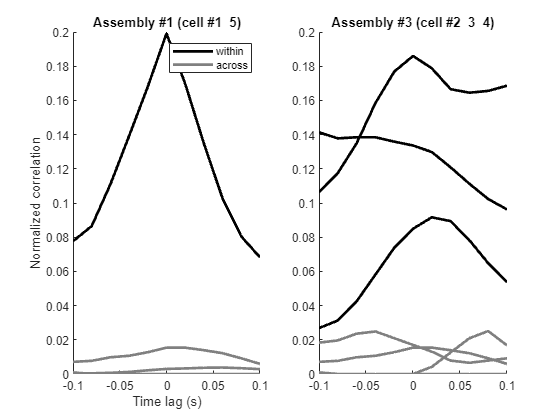

figure;

nass = numel(assList);
idxass = cell(nass,1);

%cell indices of the selected assemblies
for k = 1:nass
    id = find(Pat.cellAssemblies(:,assList(k)));
    idxass{k} = find(ismember(cellidx, id));
end

cellList = 1:size(ccAll,1);

for k = 1:nass
    subplot(1,nass,k);
    for icell1 = 1:numel(idxass{k})-1
        %plotting cross-correlations between cells within the assembly
        for icell2 = icell1+1:numel(idxass{k})
            hold on;
            p1 = plot(lagbins, squeeze(ccAll(idxass{k}(icell1), idxass{k}(icell2),:)), 'k', 'LineWidth', 2);
        end
        
        %plotting cross-correlations between cells across assemblies
        outidx = find(~ismember(cellList,idxass{k}));
        for icell2 = 1:numel(outidx)
            hold on;
            p2 = plot(lagbins, squeeze(ccAll(idxass{k}(icell1), outidx(icell2),:)),'Color', [0.5 0.5 0.5], 'LineWidth', 2);
        end
    end
    
    %Label, legend, title
    if k == 1
        legend([p1 p2], {'within','across'});
        ylabel('Normalized correlation');
        xlabel('Time lag (s)')
    end
    title(['Assembly #' num2str(assList(k)) ' (cell #' num2str(idxass{k}(:)') ')']);
end

That looks consistent with our expectations: cells within the same assemblies show higher correlations compared to those between different assemblies. Nevertheless, it's important to ascertain that these pair-wise correlations aren't influenced by an underlying latent variable causing coordinated fluctuations. For instance, if these neurons share a similar preferred location, we expect them to fire together as the animal reaches that place. Similarly, in the case of speed-related activity, when the animal runs faster, we anticipate these neurons to concurrently increase their firing rates.

### 3.3.3 Signal correlations and trial-bytrial correlations

To assess signal correlation, which refers to correlations in shared responses to position or speed, we can use a shuffling approach that disrupts trial-by-trial correlations, by computing the pair-wise correlations, but with spike trains shuffled within position, direction and speed bins.

To do that we will first start by binning positions and speeds.

%Discretizing position according to crossparams.binedges{1}
Xpos = Nav.(crossparams.variablenames{1});
Xpos_discrete = discretize(Xpos, crossparams.binedges{1});

%number of position bins
nXbins = numel(crossparams.binedges{1}) - 1;

%Discretizing speed according to crossparams.binedges{2}
%Speeds are first clamped within the speed range
Spd = Nav.(crossparams.variablenames{2});
Spd_discrete = discretize(Spd, crossparams.binedges{2});

%number of speed bins
nSpdbins = numel(crossparams.binedges{2}) - 1;

%Discretizing position according to crossparams.binedges{1}
XDir = Nav.(crossparams.variablenames{3});
XDir_discrete = discretize(XDir, crossparams.binedges{1});

%number of direction bins
nDirbins = numel(crossparams.binedges{3}) - 1;

We can then proceed to compute pair-wise correlations in the same manner as above, but this time by shuffling the spike trains within bins. Specifically, we will interchange time bins that correspond to the same position, same speed and same direction of travel.

%Initializing the cross-correlation matrix for the shuffle controls
ccSigShf = NaN(ncells, ncells, numel(idxwin), crossparams.nShuffle);

%Initializing the random number generator for reproducibility purposes
s = RandStream('mt19937ar','Seed',0);

%Computing cross-correlation after shuffling spikes within position,
%speed and direction bins.
for ishf = 1:crossparams.nShuffle
    %Shuffling spike trains
    spikeTrainShf = spikeTrain;
    for ipos = 1:nXbins
        for ispd = 1:nSpdbins
            for idir = 1:nDirbins
                idx = find(tidx & Xpos_discrete == ipos & Spd_discrete == ispd & XDir_discrete == idir);
                for icell = 1:ncells
                    idxshf = idx(randperm(s,numel(idx)));
                    spikeTrainShf(idx,icell) = spikeTrainShf(idxshf,icell);
                end
            end
        end
    end

    %Smoothing spike trains over a time window.
    spkCountShf = zeros(size(spikeTrainShf));
    decbinwin = 2 * floor(0.5 * crossparams.timewin * crossparams.sampleRate) + 1;
    for icell = 1:size(spikeTrainShf,2)
        spkCountShf(:,icell) = smooth(spikeTrainShf(:,icell), decbinwin, 'moving') * decbinwin;
    end

    for icell1 = 1:ncells
        for icell2 = icell1+1:ncells
            %Spike indices that are in the right range of time indices
            st1 = find(tidx & spkCountShf(:,icell1) > 0);

            %Removing values from the spike counts that are not in the
            %right range of time indices
            sp1 = spkCountShf(:,icell1);
            sp2 = spkCountShf(:,icell2);
            sp1(~tidx) = NaN;
            sp2(~tidx) = NaN;

            %Getting the snipets of cell2's spikes around cell1's spikes
            [~, ~, l] = ComputeTriggeredAverage(sp2, st1, idxwin, spkCountShf(st1,icell1));

            %Unnormalized cross-correlation
            c12 = sum(l, 1, 'omitnan');

            %Auto-correlations at zero lag
            c1 = sum(sp1.^2, 'omitnan');
            c2= sum(sp2.^2, 'omitnan');

            %Normalized cross-correlation
            ccSigShf(icell1,icell2,:,ishf) = c12 / sqrt(c1 * c2);
            ccSigShf(icell2,icell1,:,ishf) = c12 / sqrt(c1 * c2);
        end
    end
end

Plot one pair-wise correlation for each selected  assembly, together with their corresponding shuffle controls (or maybe just 20 of them).

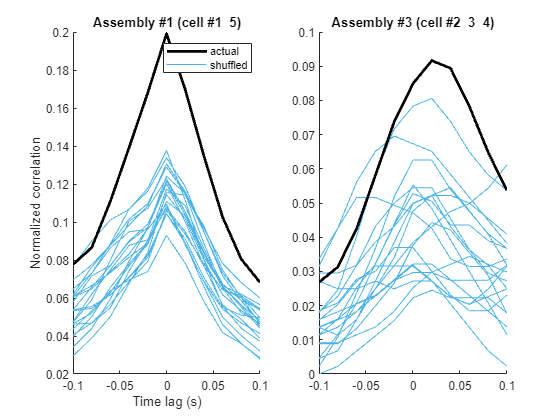

figure;

nass = numel(assList);
idxass = cell(nass,1);

%cell indices of the selected assemblies
for k = 1:nass
    id = find(Pat.cellAssemblies(:,assList(k)));
    idxass{k} = find(ismember(cellidx, id));
end

cellList = 1:size(ccAll,1);

for k = 1:nass
    subplot(1,nass,k);
    for icell1 = 1:numel(idxass{k})-1
        %plotting the shuffle controls
        hold on;
        p2 = plot(lagbins, squeeze(ccSigShf(idxass{k}(1), idxass{k}(2), :, 1:20)),'Color', [0.3 0.7 0.9], 'LineWidth', 0.5);

        %plotting one cross-correlation from within the assembly
        p1 = plot(lagbins, squeeze(ccAll(idxass{k}(1), idxass{k}(2), :)), 'k', 'LineWidth', 2);
    end
    
    %Label, legend, title
    if k == 1
        legend([p1 p2(1)], {'actual','shuffled'});
        ylabel('Normalized correlation');
        xlabel('Time lag (s)')
    end
    title(['Assembly #' num2str(assList(k)) ' (cell #' num2str(idxass{k}(:)') ')']);
end

This analysis can be run by calling CrossSpkAnalysis.

Cross = CrossSpkAnalysis(Nav, Spk.spikeTrain, crossparams);

Plot the pair-wise correlation within assemblies, the average of the shuffle controls and their s.d.

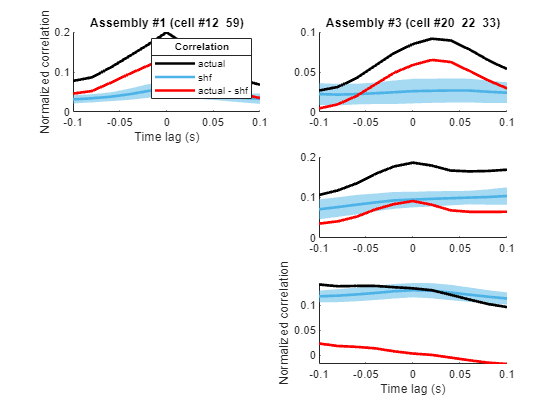

figure;

nass = numel(assList);
idxass = cell(nass,1);

%cell indices of the selected assemblies
for k = 1:nass
    idxass{k} = find(Pat.cellAssemblies(:,assList(k)));
end

cellList = 1:size(Cross.ccAll,1);

%for subplot: max number of pair-wise correlations across assemblies
ncellmax = max(sum(Pat.cellAssemblies(:,assList),1));
npairmax = ncellmax * (ncellmax -1) / 2;

for k = 1:nass
    i = 0;
    %plotting cross-correlations between cells within the assembly
    for icell1 = 1:numel(idxass{k})-1
        for icell2 = icell1+1:numel(idxass{k})
            i = i + 1;
            subplot(npairmax, nass, (i-1) * nass + k);
            %signal corrlelation estimated by shf control
            p1 = plot(Cross.lagbins, squeeze(Cross.ccSig(idxass{k}(icell1), idxass{k}(icell2),:)), 'Color', [0.3 0.7 0.9], 'LineWidth', 2);
            %shf -/+ s.d.
            hold on;
            lo = Cross.ccSig(idxass{k}(icell1), idxass{k}(icell2),:) - Cross.ccSigSD(idxass{k}(icell1), idxass{k}(icell2),:);
            hi = Cross.ccSig(idxass{k}(icell1), idxass{k}(icell2),:) + Cross.ccSigSD(idxass{k}(icell1), idxass{k}(icell2),:);
            ciplot(Cross.lagbins, squeeze(lo), squeeze(hi), [0.3 0.7 0.9], 0.5);
            
            %actual cross-correlation
            hold on;
            p2 = plot(Cross.lagbins, squeeze(Cross.ccAll(idxass{k}(icell1), idxass{k}(icell2),:)), 'k', 'LineWidth', 2);

            %residual (or noise) cross-correlation
            hold on;
            p3 = plot(Cross.lagbins, squeeze(Cross.ccNoise(idxass{k}(icell1), idxass{k}(icell2),:)), 'r', 'LineWidth', 2);

            set(gca,'Box','off');
        end
    end
    
    %Label, legend, title
    xlabel('Time lag (s)')
    ylabel('Normalized correlation');
    if k == 1
        lgd = legend([p2 p1 p3], {'actual','shf','actual - shf'});
        title(lgd,'Correlation')
    end
    subplot(npairmax, nass, k);
    title(['Assembly #' num2str(assList(k)) ' (cell #' num2str(idxass{k}(:)') ')']);
end

What strategy would you use to make sure that the cell assemblies that are detected in the cell assembly analysis reflect neurons whose coincidental firing is not a mere consequence of their shared selectivity to positions?